% 1. Wygeneruj N=1000 próbek sygnału sinusoidalnego x(t)=Asin(2πfxt) o amplitudzie A=5 i o częstotliwości
% fx=10 Hz, spróbkowanego z częstotliwością fp=1000 Hz. Narysuj ten sygnał.
disp('1. Wygeneruj N=1000 próbek sygnału sinusoidalnego x(t)=Asin(2πfxt) o amplitudzie A=5 i o częstotliwości fx=10 Hz, spróbkowanego z częstotliwością fp=1000 Hz. Narysuj ten sygnał.')

1. Wygeneruj N=1000 próbek sygnału sinusoidalnego x(t)=Asin(2πfxt) o amplitudzie A=5 i o częstotliwości fx=10 Hz, spróbkowanego z częstotliwością fp=1000 Hz. Narysuj ten sygnał.


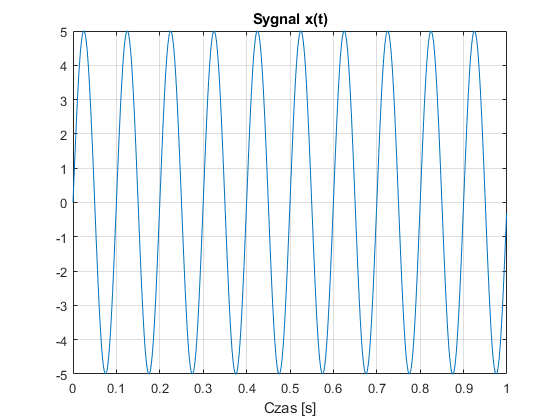

N=1000; A=5; fx=10; fp=1000;   %parametry sygnalu
dt = 1/fp;                      %okres probkowania
t = dt*(0:N-1);                 %wektor czasu
x = A*sin(2*pi*fx*t);           % sygnal
plot(t, x); grid; title('Sygnal x(t)'); xlabel('Czas [s]');


%  Obliczenie parametrow sygnalu
x_sred = mean(x), x_sred2 = sum(x)/N

x_sred = -8.4438e-16

x_sred2 = -8.4438e-16

x_max = max(x), x_min = min(x), x_std1 = std(x)

x_max = 5

x_min = -5

x_std1 = 3.5373

x_std2 = sqrt( sum((x-mean(x)).^2) / (N-1))

x_std2 = 3.5373

x_eng = dt*sum(x.^2)    % energia sygnalu

x_eng = 12.5000

x_moc = 1/N * x_eng     % moc sygnalu

x_moc = 0.0125

x_skut = sqrt(x_moc)    % wartosc skuteczna

x_skut = 0.1118

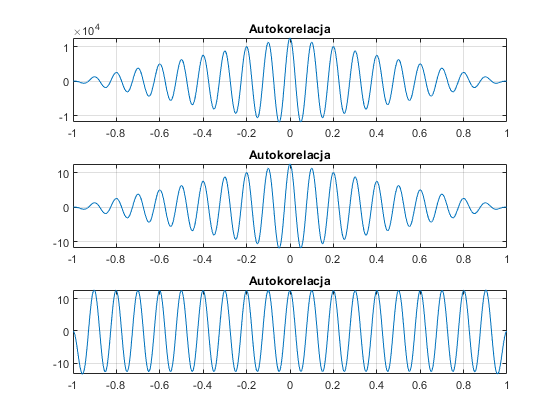


% Obliczenie korelacji R1, R2 i R3 syganlu
R1 = xcorr(x);              % korelacja nie umormowana
R2 = xcorr(x, 'biased');    % unormowana przez dlugosc /N
R3 = xcorr(x, 'unbiased');  % unormowana przez /(N-abs(k))
tR = [-fliplr(t) t(2:N)]; R = [R1; R2; R3];
for i=1:3
    subplot(3, 1, i);
    plot(tR, R(i, :)); grid; title('Autokorelacja');
end

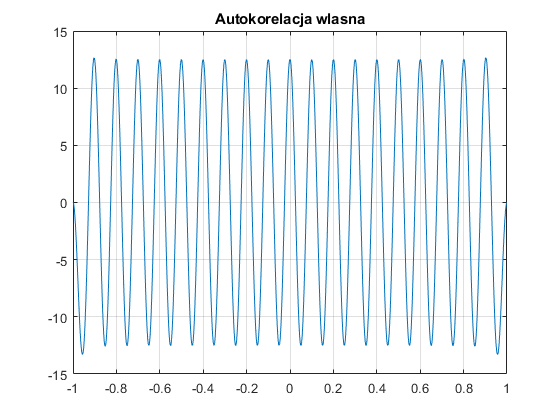


% wyznaczenie autokorelacji samemu
R_w = zeros(size(x));
for k=0:N-1
    R_w(k+1) = sum( x(1:N-k).*x(1+k:N) ) / (N-k);
end
R_w = [fliplr(R_w) R_w(2:N)];
figure();
plot(tR, R_w); grid; title('Autokorelacja wlasna');

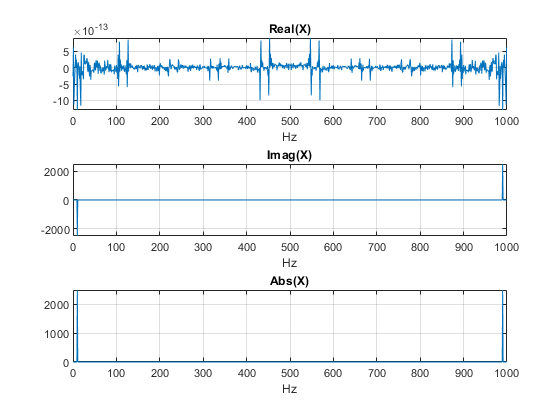


% obliczenia wspolczynnikow szeregu Fouriera sygnalu

X = fft(x);                 % szybka dyskretna transf Fouriera
df = 1/(N*dt);              % czestotliwosc podstawowa f0=df=1/T
f = df * (0:N-1);
subplot(3,1,1); plot(f, real(X)); grid; title('Real(X)'); xlabel('Hz');
subplot(3,1,2); plot(f, imag(X)); grid; title('Imag(X)'); xlabel('Hz');
subplot(3,1,3); plot(f, abs(X)); grid; title('Abs(X)'); xlabel('Hz');

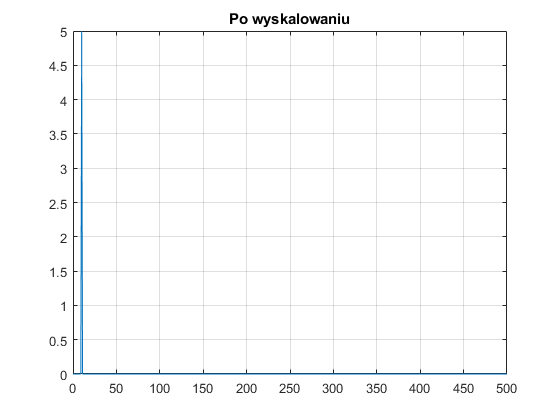

figure();
plot(f(1:N/2+1), abs(X(1:N/2+1))/(N/2) ); grid; title('Po wyskalowaniu');

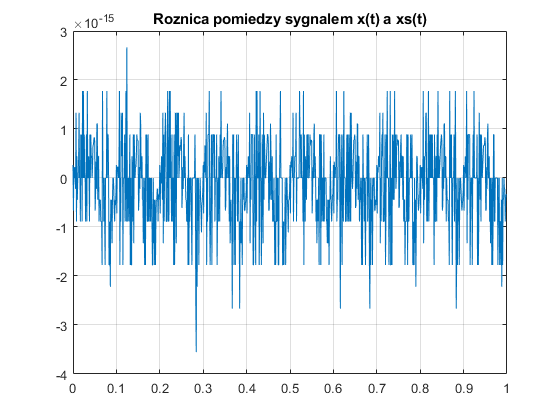


% zsyntezuj sygnal na podstawie wspolczynnikow szeregu i porownaj z
% orginalem
xs = ifft(X);
figure();
plot(t, real(x-xs)); grid; title('Roznica pomiedzy sygnalem x(t) a xs(t)');

% 2. Wygeneruj N=1000 próbek szumu o rozkładzie równomiernym i normalnym (gaussowskim). Wyznacz dla nich
% funkcję autokorelacji, autokowariancji, histogram, szereg Fouriera i periodogram.
disp('2. Wygeneruj N=1000 próbek szumu o rozkładzie równomiernym i normalnym (gaussowskim). Wyznacz dla nich funkcję autokorelacji, autokowariancji, histogram, szereg Fouriera i periodogram.')

2. Wygeneruj N=1000 próbek szumu o rozkładzie równomiernym i normalnym (gaussowskim). Wyznacz dla nich funkcję autokorelacji, autokowariancji, histogram, szereg Fouriera i periodogram.


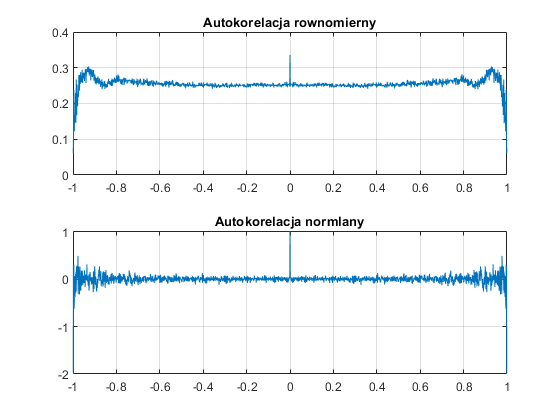

s1 = rand(1, N); s2=randn(1, N);
R1 = xcorr(s1, 'unbiased'); R2 = xcorr(s2, 'unbiased');
figure();
subplot(2,1,1); plot(tR, R1); grid; title('Autokorelacja rownomierny');
subplot(2,1,2); plot(tR, R2); grid; title('Autokorelacja normlany');

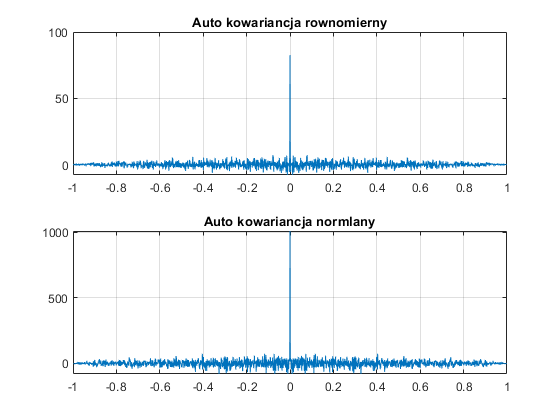


C1 = xcov(s1); C2 = xcov(s2);
figure();
subplot(2,1,1); plot(tR, C1); grid; title('Auto kowariancja rownomierny');
subplot(2,1,2); plot(tR, C2); grid; title('Auto kowariancja normlany');

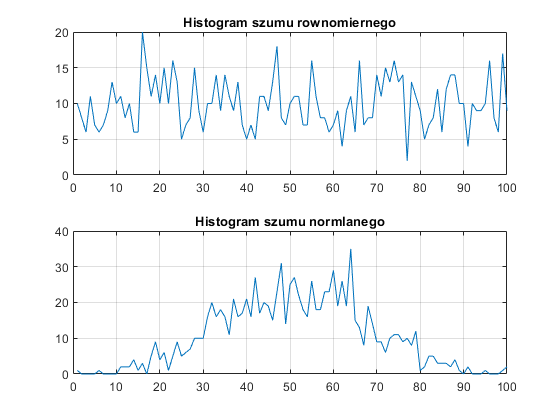


Hs1 = hist(s1, 100); Hs2 = hist(s2, 100);
figure();
subplot(2,1,1); plot(Hs1); grid; title('Histogram szumu rownomiernego');
subplot(2,1,2); plot(Hs2); grid; title('Histogram szumu normlanego');

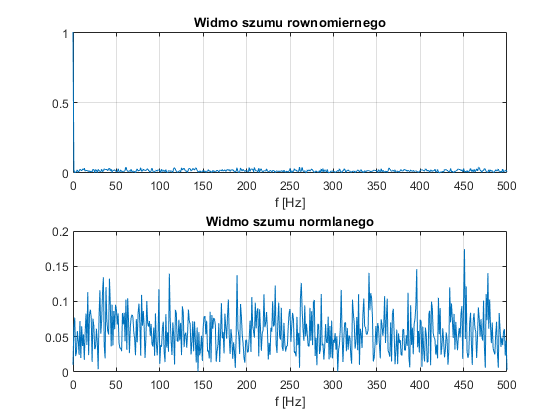


S1 = fft(s1); S2 = fft(s2);
figure();
subplot(2,1,1); plot(f(1:N/2+1), abs(S1(1:N/2+1))/(N/2)); grid; xlabel('f [Hz]'); title('Widmo szumu rownomiernego');
subplot(2,1,2); plot(f(1:N/2+1), abs(S2(1:N/2+1))/(N/2)); grid; xlabel('f [Hz]'); title('Widmo szumu normlanego');

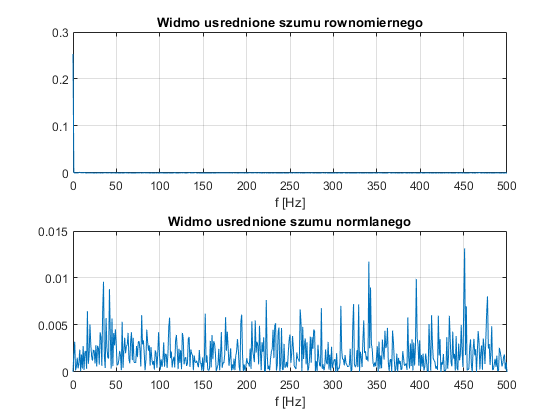


[Pss1, fss1] = periodogram(s1, [], [], fp); [Pss2, fss2] = periodogram(s2, [], [], fp);
figure();
subplot(2,1,1); plot(fss1, Pss1); grid; title('Widmo usrednione szumu rownomiernego'); xlabel('f [Hz]');
subplot(2,1,2); plot(fss2, Pss2); grid; title('Widmo usrednione szumu normlanego'); xlabel('f [Hz]');

% 3. Dodaj sygnały z punktu 1 i 2. Wyznacz i narysuj funkcję autokorelacji, autokowariancji i histogram sygnału
% sumarycznego.
disp('Zadanie 3. Dodaj sygnały z punktu 1 i 2. Wyznacz i narysuj funkcję autokorelacji, autokowariancji i histogram sygnału sumarycznego.')

Zadanie 3. Dodaj sygnały z punktu 1 i 2. Wyznacz i narysuj funkcję autokorelacji, autokowariancji i histogram sygnału sumarycznego.


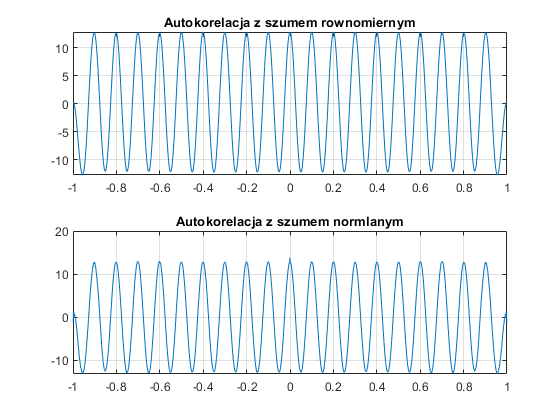

x_new1 = x + s1; x_new2 = x + s2;

R1 = xcorr(x_new1, 'unbiased'); R2 = xcorr(x_new2, 'unbiased');
figure();
subplot(2,1,1); plot(tR, R1); grid; title('Autokorelacja z szumem rownomiernym');
subplot(2,1,2); plot(tR, R2); grid; title('Autokorelacja z szumem normlanym');

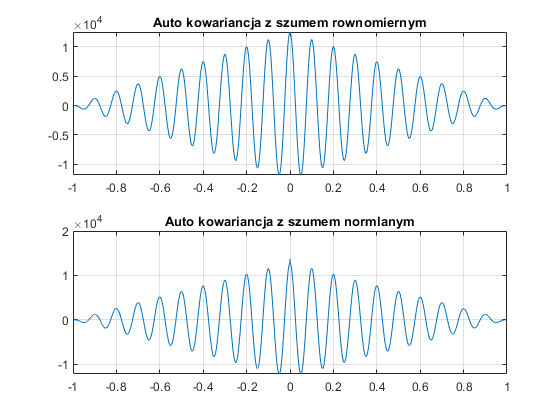


C1 = xcov(x_new1); C2 = xcov(x_new2);
figure();
subplot(2,1,1); plot(tR, C1); grid; title('Auto kowariancja z szumem rownomiernym');
subplot(2,1,2); plot(tR, C2); grid; title('Auto kowariancja z szumem normlanym');

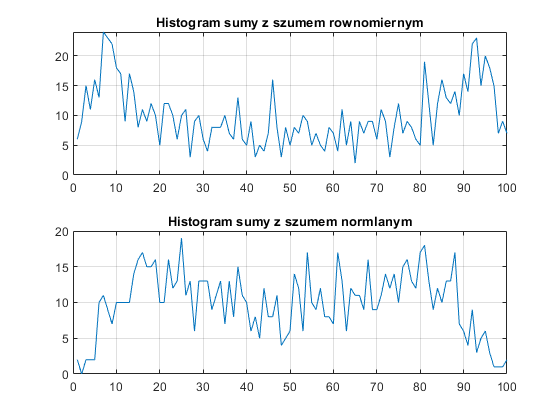


Hs1 = hist(x_new1, 100); Hs2 = hist(x_new2, 100);
figure();
subplot(2,1,1); plot(Hs1); grid; title('Histogram sumy z szumem rownomiernym');
subplot(2,1,2); plot(Hs2); grid; title('Histogram sumy z szumem normlanym');

% 4. Powtórz operacje z punktu 3 po dodaniu do sygnału 1+2 jeszcze jednej sinusoidy o częstotliwości 250 Hz.
disp('4. Powtórz operacje z punktu 3 po dodaniu do sygnału 1+2 jeszcze jednej sinusoidy o częstotliwości 250 Hz.')

4. Powtórz operacje z punktu 3 po dodaniu do sygnału 1+2 jeszcze jednej sinusoidy o częstotliwości 250 Hz.


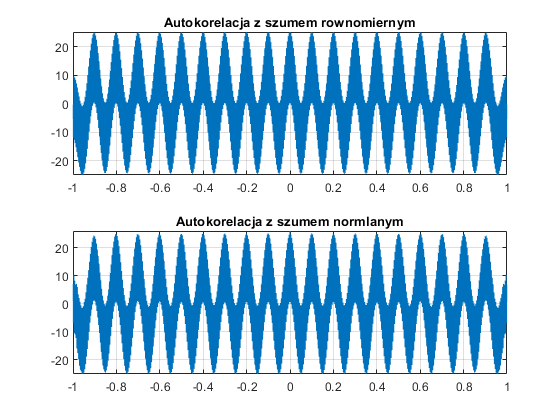

x_new1 = x + s1 + A*sin(2*pi*250*t); x_new2 = x + s2 + A*sin(2*pi*250*t);

R1 = xcorr(x_new1, 'unbiased'); R2 = xcorr(x_new2, 'unbiased');
figure();
subplot(2,1,1); plot(tR, R1); grid; title('Autokorelacja z szumem rownomiernym');
subplot(2,1,2); plot(tR, R2); grid; title('Autokorelacja z szumem normlanym');

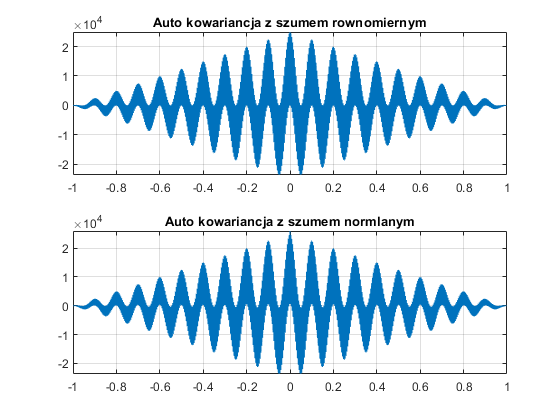


C1 = xcov(x_new1); C2 = xcov(x_new2);
figure();
subplot(2,1,1); plot(tR, C1); grid; title('Auto kowariancja z szumem rownomiernym');
subplot(2,1,2); plot(tR, C2); grid; title('Auto kowariancja z szumem normlanym');

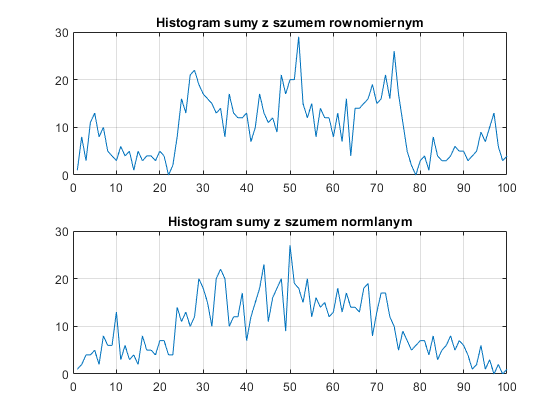


Hs1 = hist(x_new1, 100); Hs2 = hist(x_new2, 100);
figure();
subplot(2,1,1); plot(Hs1); grid; title('Histogram sumy z szumem rownomiernym');
subplot(2,1,2); plot(Hs2); grid; title('Histogram sumy z szumem normlanym');

% 5. Zmoduluj w amplitudzie sygnał sinusoidalny z punktu pierwszego.
disp('5. Zmoduluj w amplitudzie sygnał sinusoidalny z punktu pierwszego.')

5. Zmoduluj w amplitudzie sygnał sinusoidalny z punktu pierwszego.


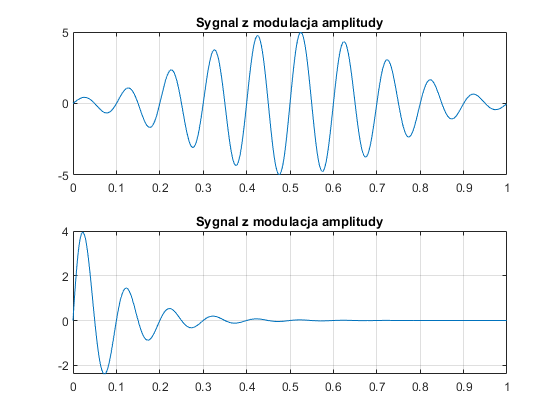

figure();
ampl = hamming(N)'; % okno hamminga
y1 = ampl.*x; subplot(2,1,1); plot(t, y1); grid; title('Sygnal z modulacja amplitudy')

ampl = exp(-10*t); % okno hamminga
y2 = ampl.*x; subplot(2,1,2); plot(t, y2); grid; title('Sygnal z modulacja amplitudy')

% 6. Wygeneruj sygnał sinusoidalny z liniową modulacja częstotliwości (ω=ωx+αt) oraz z sinusoidalną modulacją
% częstotliwości ((ω=ωx+sin(ωmt)).
disp('6. Wygeneruj sygnał sinusoidalny z liniową modulacja częstotliwości (ω=ωx+αt) oraz z sinusoidalną modulacją częstotliwości ((ω=ωx+sin(ωmt)).')

6. Wygeneruj sygnał sinusoidalny z liniową modulacja częstotliwości (ω=ωx+αt) oraz z sinusoidalną modulacją częstotliwości ((ω=ωx+sin(ωmt)).


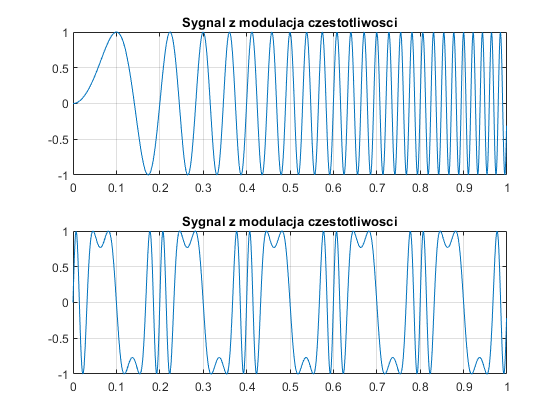

figure();
fx = 0; alfa = 50;
y3 = sin(2*pi* (fx*t + 0.5*alfa*t.^2)); subplot(2,1,1); plot(t, y3); grid; title('Sygnal z modulacja czestotliwosci')

fx = 10; fm = 5; df = 25;
y4 = sin(2*pi*(fx*t + df * sin(2*pi*fm*t)/(2*pi*fm))); subplot(2,1,2); plot(t, y4); grid; title('Sygnal z modulacja czestotliwosci')

% 7. Sklej dwa sygnały.
disp('7. Sklej dwa sygnały.')

7. Sklej dwa sygnały.


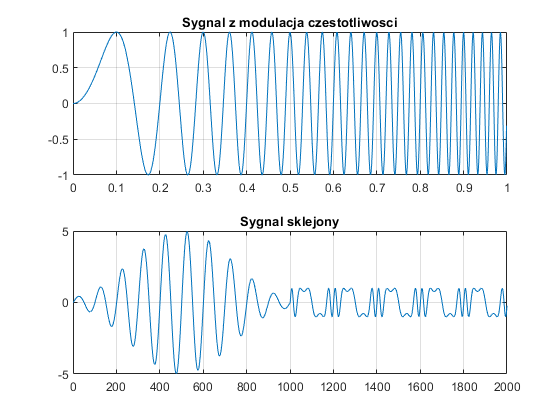

y5 = [ y1 y4];
plot(y5); grid; title('Sygnal sklejony');

% 8. „Spleć" ze sobą dwa sygnały, czyli dokonaj filtracji jednego z nich przez
% drugi.
disp('8. „Spleć" ze sobą dwa sygnały, czyli dokonaj filtracji jednego z nich przez drugi.')

8. „Spleć" ze sobą dwa sygnały, czyli dokonaj filtracji jednego z nich przez drugi.


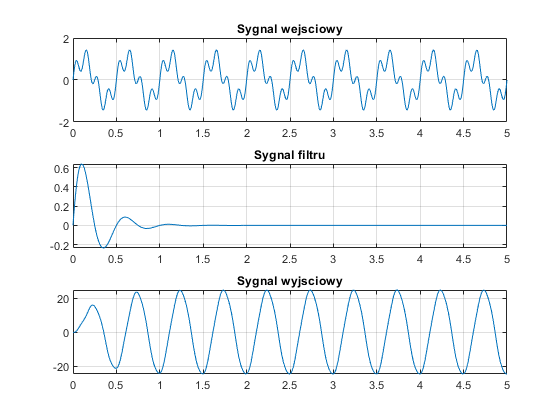

T = 5; N = 1000; dt = T/N; t = dt*(0:N);
x = sin(2*pi*t*2) + 0.5*sin(2*pi*t*8);
h = sin(2*pi*2*t).*exp(-4*t);
y = conv(x, h);
figure()
subplot(3,1,1); plot(t, x); grid; title('Sygnal wejsciowy');
subplot(3,1,2); plot(t, h); grid; title('Sygnal filtru');
subplot(3,1,3); plot(t, y(1:N+1)); grid; title('Sygnal wyjsciowy');

% 9. Skwantuj sygnał x(t) z punktu 8
disp('9. Skwantuj sygnał x(t) z punktu 8')

9. Skwantuj sygnał x(t) z punktu 8


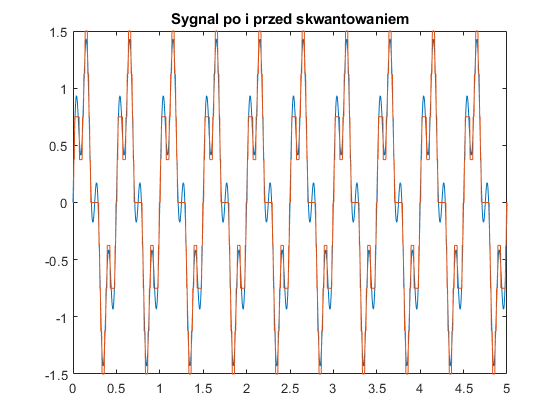

figure(); plot(t, x); hold on;
x_min = -1.5; x_max = 1.5; x_zakres = x_max-x_min;
Nb = 3; Nq = 2^Nb;  %Nb - liczba bitow, Nq - liczba przedzialow kwantowania
dx = x_zakres/Nq;   % szerokosc przedzialu
xq = dx*round(x/dx);    %kwatnyzacja
plot(t, xq); title('Sygnal po i przed skwantowaniem')